# Examen RA3L - Matlab Partie 2                /10

Le fichier Data_LED.mat contient la tension et le courant, mesurés par un oscilloscope, sur une ampoule LED branchée au secondaire d'un transformateur 230 V / 12 V. Une photo du montage et une capture d'écran de l'oscilloscope (avec la tension en jaune (CH1) et le courant en bleu (CH2)) sont présentées ci-dessous. NB: 5 tours de fil ont été bobinés dans la pince ampèremétrique pour augmenter sa sensibilté : la valeur réelle du courant vaut donc un cinquième de celle affichée à l'oscilloscope. 

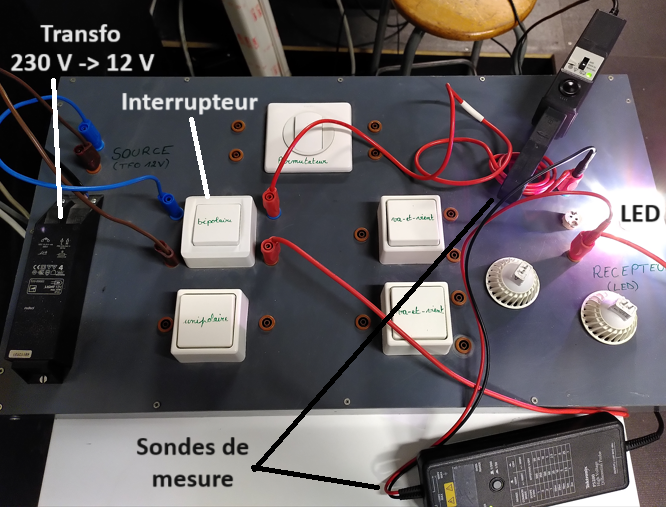  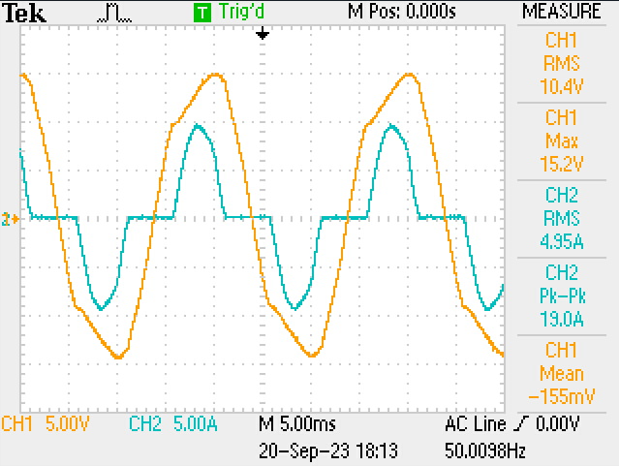

**1) Charger les données et visualiser le courant et la tension. Diviser le courant par 5 pour retrouver sa valeur réelle ***(1 point)***. Déterminer ensuite la fréquence (Fs) et la période d'échantillonage (Ts) ***(0,5 point)***. **

clear all 
close all
load Data_LED.mat
whos

  Name         Size            Bytes  Class     Attributes

  is        2500x1             20000  double              
  t         2500x1             20000  double              
  us        2500x1             20000  double              



is_real = is / 5

is_real =     1.4400
    1.4000
    1.4000
    1.4000
    1.3600
    1.3600
    1.3200
    1.3200
    1.2800
    1.2800
    1.2400
    1.2400
    1.2000
    1.2000
    1.2000



Ts = t(2) - t(1) %priode echantilonnage 

Ts = 2.0000e-05

Fs = 1 / Ts %fréq echantilonnage

Fs = 5.0000e+04

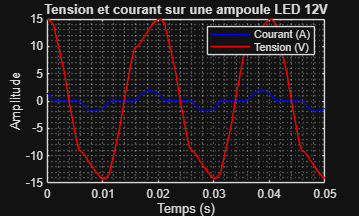


figure
plot(t, is_real, '-b', 'DisplayName', 'Courant (A)') 
hold on
plot(t, us, '-r', 'DisplayName', 'Tension (V)') 
hold off
title('Tension et courant sur une ampoule LED 12V')
xlabel('Temps (s)')
ylabel('Amplitude')
legend('show')
grid minor 

Résultat attendu :

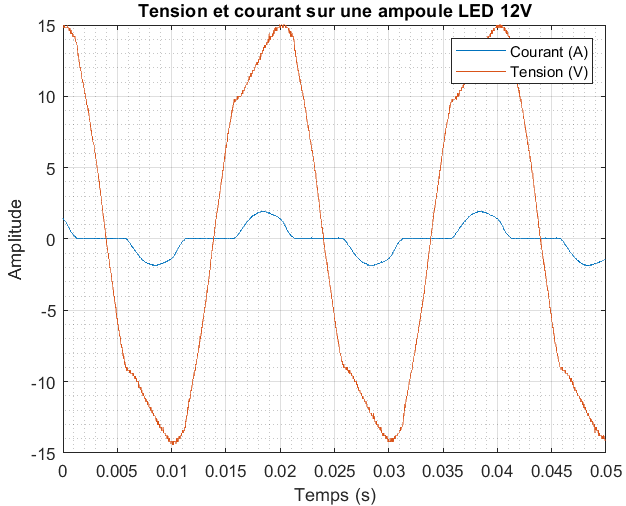

**2) Corriger le code fourni permettant d'appliquer la FFT sur chaque signal (courant **`is`** et tension **`us`**) en justifiant les corrections exécutées ****sur feuille annexe****. ***(2,5 point)*

Voici le code fourni à corriger :  

*        N=length(t)*

       * X_is=fft(is);*

*        Amp_is=X_is(1:N/2+1);*

*        Phase_is = angle(X_is(1:N/2+1))*180/pi;*

*        n=0:1:N/2+1;*

*        dF=N*Ts;*

*        f=n*dF;*

*        subplot(2,1,1)*

*        stem(f,Amp_is)*

*        subplot(2,1,2)*

*        stem(f,Phase_is)*

**Implémenter le code corrigé pour appliquer la FFT et visualiser le contenu fréquentiel du signal de courant. Faire de même avec le signal de tension et afficher sa FFT sur le même graphe** *(0,5 points)*.

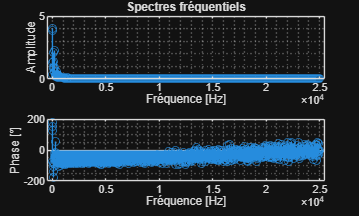

N = length(t);
X_is = fft(is);
Amp_is = abs(X_is(1:N/2+1)) /N;
Amp_is(2:end) = 2*Amp_is(2:end);
Phase_is = angle(X_is(1:N/2+1))*180/pi;
dF = 1/(N*Ts);
f = (0:(N/2))*dF;
figure
subplot(2,1,1)
stem(f, Amp_is, 'o')
title('Spectres fréquentiels')
xlabel('Fréquence [Hz]')
ylabel('Amplitude')
grid minor
%xlim([0 3])
%ylim([0 10])
subplot(2,1,2)
stem(f, Phase_is, 'o')
xlabel('Fréquence [Hz]')
ylabel('Phase [°]')
grid minor

Résultat attendu : 

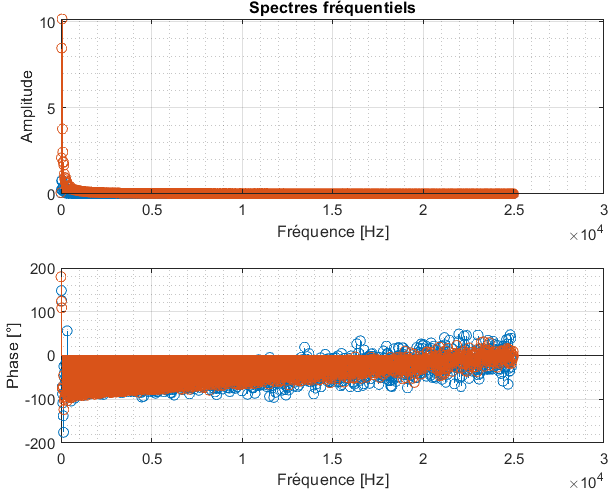

**3) En supposant que les spectres obtenus à la question 2 n'ont pas de contenu fréquentiel au-delà de 500 Hz, peut-on dire que la condition de Nyquist a été respectée ? A partir du graphe temporel obtenu à la question 1 (ou de la capture d'écran de l'oscillo du début de l'énoncé), peut-on dire que le signal a été correctement fenêtré ? Justifier, à chaque fois, ****sur feuille annexe****, avec du texte et/ou avec un/des schémas ***(1 point)***.**

**4) Appliquer les corrections nécessaires (ou pas) pour implémenter à nouveau la FFT sur chaque signal et visualiser le spectre fréquentiel uniquement entre 0 et 500 Hz. Mettre à zéro la phase des composantes du spectre dont l'amplitude est inférieure à 0,1 volt ou 0,1 ampère ***(1,5 point)***.**

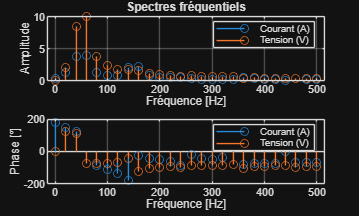


N = length(t);
X_is = fft(is);
X_us = fft(us);
Amp_is = abs(X_is(1:N/2+1)) / N;
Amp_is(2:end) = 2 * Amp_is(2:end);
Phase_is = angle(X_is(1:N/2+1)) * 180 / pi;
Amp_us = abs(X_us(1:N/2+1)) / N;
Amp_us(2:end) = 2 * Amp_us(2:end);
Phase_us = angle(X_us(1:N/2+1)) * 180 / pi;
% Mettr à zéro quand cest plus petit que 0.1
Phase_is(Amp_is < 0.1) = 0;
Phase_us(Amp_us < 0.1) = 0;
% l'axe des fréq
dF = 1 / (N * Ts);
f = (0:(N/2)) * dF;
% LIMITE A 500 HZ
limite_f = 500;
index_limite = f <= limite_f;
%les spectres d'amplitude
figure;
subplot(2,1,1);
stem(f(index_limite), Amp_is(index_limite), 'o', 'DisplayName', 'Courant (A)');
hold on;
stem(f(index_limite), Amp_us(index_limite), 'o','DisplayName', 'Tension (V)');
hold off;
title('Spectres fréquentiels');
xlabel('Fréquence [Hz]');
ylabel('Amplitude');
legend;
grid on;
%les phase
subplot(2,1,2);
stem(f(index_limite), Phase_is(index_limite), 'o', 'DisplayName', 'Courant (A)');
hold on;
stem(f(index_limite), Phase_us(index_limite), 'o', 'DisplayName', 'Tension (V)');
hold off;
xlabel('Fréquence [Hz]');
ylabel('Phase [°]');
legend;
grid on;

Résultat attendu :

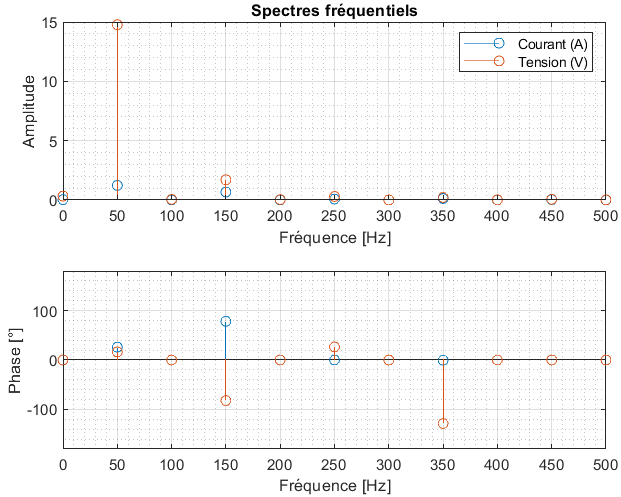

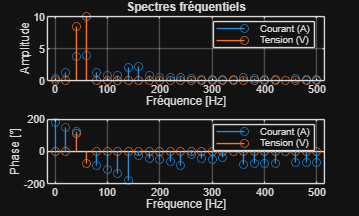

%TEST

N = length(t);
X_is = fft(is);
X_us = fft(us);
Amp_is = abs(X_is(1:N/2+1)) / N;
Amp_is(2:end) = 2 * Amp_is(2:end);
Phase_is = angle(X_is(1:N/2+1)) * 180 / pi;
Amp_us = abs(X_us(1:N/2+1)) / N;
Amp_us(2:end) = 2 * Amp_us(2:end);



Amp_us(Amp_us<5)=0;



Phase_us = angle(X_us(1:N/2+1)) * 180 / pi;
% Mettr à zéro quand cest plus petit que 0.1
Phase_is(Amp_is < 0.1) = 0;
Phase_us(Amp_us < 0.1) = 0;
% l'axe des fréq
dF = 1 / (N * Ts);
f = (0:(N/2)) * dF;
% LIMITE A 500 HZ
limite_f = 500;
index_limite = f <= limite_f;
%les spectres d'amplitude
figure;
subplot(2,1,1);
stem(f(index_limite), Amp_is(index_limite), 'o', 'DisplayName', 'Courant (A)');
hold on;
stem(f(index_limite), Amp_us(index_limite), 'o','DisplayName', 'Tension (V)');
hold off;
title('Spectres fréquentiels');
xlabel('Fréquence [Hz]');
ylabel('Amplitude');
legend;
grid on;
%les phase
subplot(2,1,2);
stem(f(index_limite), Phase_is(index_limite), 'o', 'DisplayName', 'Courant (A)');
hold on;
stem(f(index_limite), Phase_us(index_limite), 'o', 'DisplayName', 'Tension (V)');
hold off;
xlabel('Fréquence [Hz]');
ylabel('Phase [°]');
legend;
grid on;

**5)** **Calculer la puissance active P1 transportée par les composantes fondamentales de tension et de courant via la formule ci-dessous ***(0,5 point)***.**


$$P_1 =\frac{Û_1 }{\sqrt{\;2}}\frac{Î_1 }{\sqrt{\;2}}\cos \;\left(\varphi_{U_1 } -\varphi_{I_1 } \right)=\frac{Û_1 Î_1 }{2}\cos \;\left(\varphi_{U_1 } -\varphi_{I_1 } \right)$$


où $Û_1$ et $Î_1$ représentent les amplitudes des composantes fondamentales de tension et de courant et $\varphi {\;}_{U_1 }$ et $\varphi {\;}_{I_1 }$ leurs phases respectives.


index_fondamentale = find(f > 0, 1); % Faut PRENDRE la 1ERE fréquence non nulle
U1 = Amp_us(index_fondamentale);
I1 = Amp_is(index_fondamentale);
phi_u1 = Phase_us(index_fondamentale);
phi_i1 = Phase_is(index_fondamentale);
P1 = (U1 * I1 / 2) * cosd(phi_u1 - phi_i1)

P1 = 1.2386


% code

**6) **On aimerait filtrer le signal de tension pour garder uniquement le fondamental. **Appliquer au signal initial **(variable `us`)** un filtre passe-bas dont la fréquence de coupure **$\omega_{c\;}$** permet de réduire les fréquences supérieures à 100 Hz (**$\omega_{c\;} =2\pi *100$** rad/s) avec un coefficient d'amortissement **$\xi$ à 0.6 ($\left.\xi =0\ldotp 6\right)$**.**


$$H\left(s\right)=\frac{1}{\left(\frac{s^2 }{\omega_c^2 \;}+\frac{2s\xi }{\omega {\;}_c }+1\right)}$$


**Afficher le signal de sortie **(à stocker dans la variable y)** et le signal d'entrée de ce filtre sur le même graphique ***(1 point)***.**

% code


Résultat attendu :

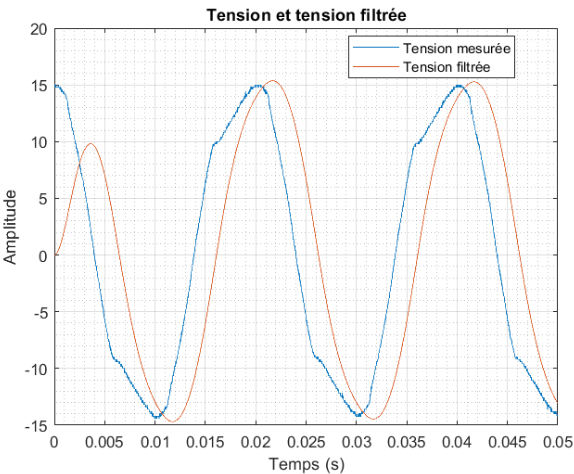

**7) Afficher**, sur le même graphique, **le diagramme de Bode du filtre passe-bas ainsi que les fréquences pour lesquelles le filtre a été sollicité **(cf. résultat de la question 4) *(1,5 point)***. **

% code

Résultat attendu :